# Objekt

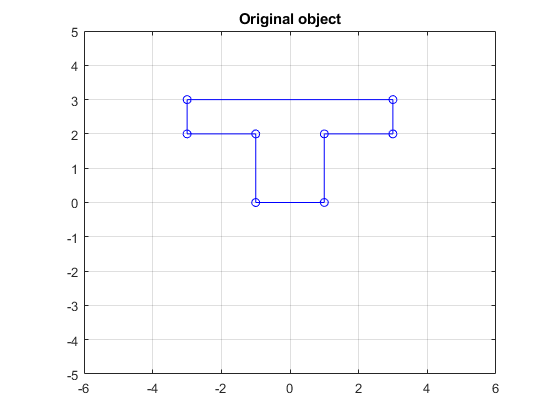


clf
clear all

X=[1 1 3 3 -3 -3 -1 -1 1
    0 2 2 3 3 2 2 0 0
    0 0 0 0 0 0 0 0 0];

plot(X(1,:),X(2,:),'b-o')


axis equal

%%plot(x,y)
xlim([-6 6]);
ylim([-5 5]);
title("Original object")

grid on

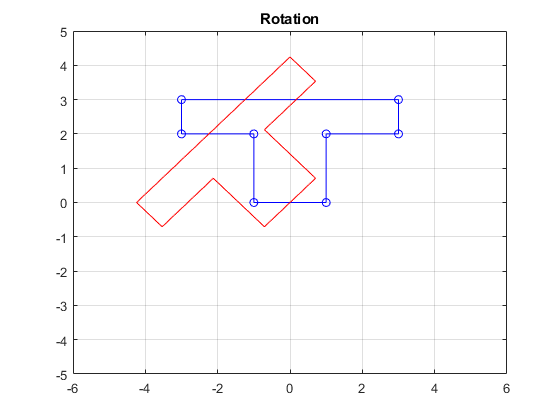

%hold on
%%Rotationsoperation:


v=pi/4;
%Rotation moturs matrisen
z=[cos(v) -sin(v)
    sin(v) cos(v)];

y1=cos(v)*X(1,:) + (-sin(v))*X(2,:);
y2=sin(v)*X(1,:) + cos(v)*X(2,:);

plot(X(1,:),X(2,:),'b-o',y1,y2,'r-')
grid on
xlim([-6 6]);
ylim([-5 5]);
title("Rotation")

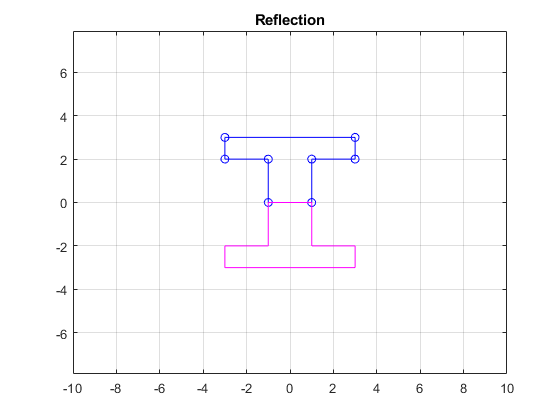


%%Spegling
v1=pi;

z1=cos(2*v1)*X(1,:) + (sin(2*v1))*X(2,:);
z2=sin(2*v1)*X(1,:) + -cos(2*v1)*X(2,:);

plot(X(1,:),X(2,:),'b-o',z1,z2,'m-')
grid on
xlim([-10 10]);
ylim([-7 7]);
title("Reflection")

axis equal

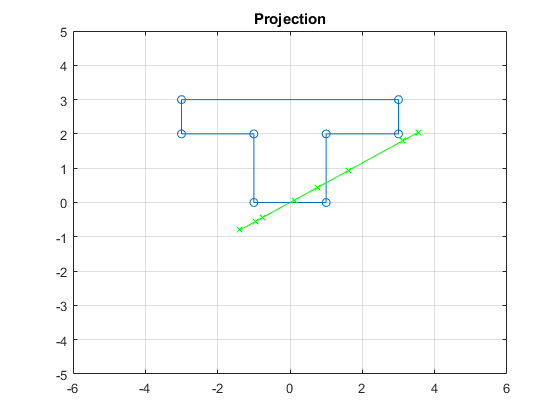

 v2=pi/6;
 c1=cos(v2)*cos(v2) * X(1,:) + (sin(v2)*cos(v2))* X(2,:);
 c2=(sin(v2)*cos(v2))*X(1,:) + sin(v2)*sin(v2)*X(2,:);
 plot(X(1,:),X(2,:),'-o',c1,c2,'gx-')
 grid on
% plot(X(1,:),X(2,:),'-o',c1,c2,'gx-')
%  xlim([-1 5]);
%  ylim([-1 6]);
xlim([-6 6]);
ylim([-5 5]);
title("Projection")

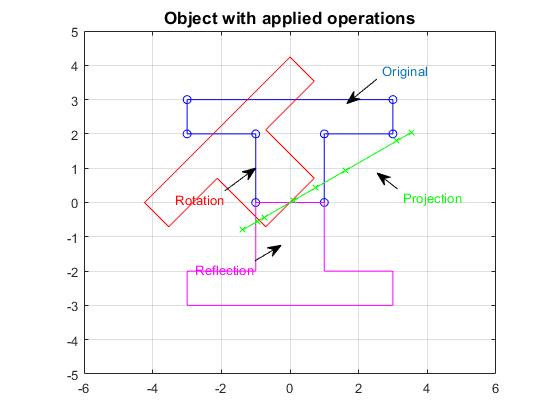



figure_all_operations(X(1,:),X(2,:),y1,y2,z1,z2,c1,c2)

xlim([-6 6]);
ylim([-5 5]);